# Project SMR_Robots

## Origin knowing 2 points

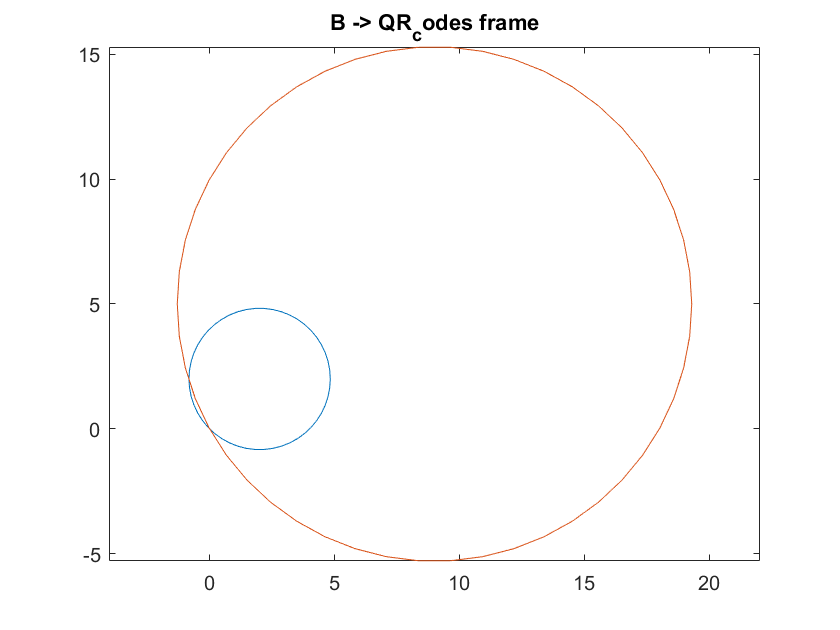

close all
clear
clc

% PTO 1 {B} - frame B (QR_codes frame)
Bx1=2;
By1=2;

% PTO 1 {A} - frame A (robot frame)
Ax1=5;
Ay1=5;

% Distance from PTO 1{B} to origin O{B}
r1 = sqrt(Bx1^2 + By1^2);

% PTO 2 {B} - frame B (QR_codes frame)
Bx2=9;
By2=5;

% PTO 2 {A} - frame A (robot frame)
Ax2=8;
Ay2=12;

% Distance from PTO 2{B} to origin O{B}
r2 = sqrt(Bx2^2 + By2^2);

syms x y
figure(1)
circle([Bx1 By1],r1)
hold on
circle([Bx2 By2],r2)
axis equal
hold off
title('{B} -> QR_codes frame')

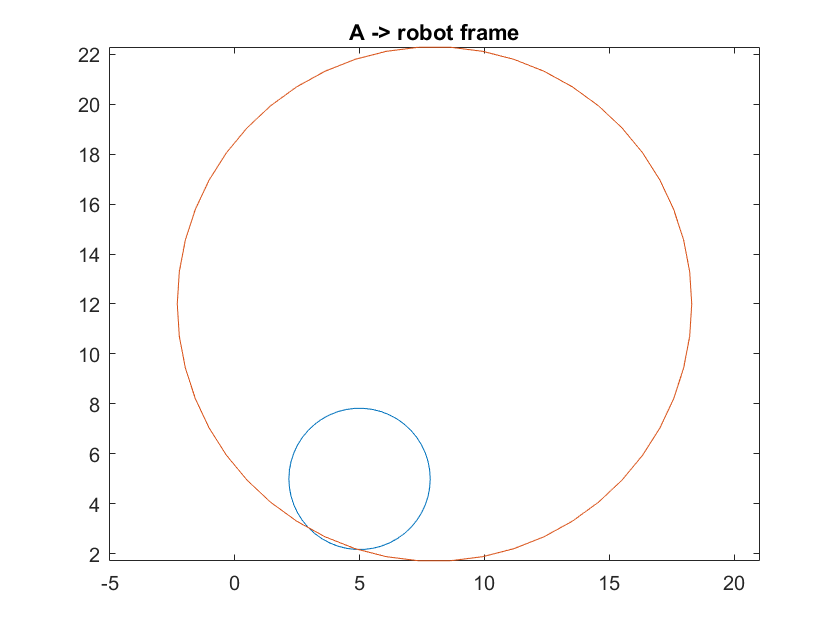


figure(2)
circle([Ax1 Ay1],r1)
hold on
circle([Ax2 Ay2],r2)
axis equal
hold off
title('{A} -> robot frame')


% Solution origin {A}
circle1_A = @(x,y)(x-Ax1).^2 + (y-Ay1).^2 -r1^2;
circle2_A = @(x,y)(x-Ax2).^2 + (y-Ay2).^2 -r2^2;

[xA,yA] = solve((x-Ax1).^2 + (y-Ay1).^2 ==r1^2,(x-Ax2).^2 + (y-Ay2).^2 ==r2^2);

disp('Solution origin 1 in frame{A}: ')

Solution origin 1 in frame{A}: 


disp(eval(xA(1)))

     3



disp(eval(yA(1)))

     3



disp('Solution origin 2 in frame{A}: ')

Solution origin 2 in frame{A}: 


disp(eval(xA(2)))

    4.9310



disp(eval(yA(2)))

    2.1724




% Solution origin {B}
circle1_B = @(x,y)(x-Bx1).^2 + (y-By1).^2 -r1^2;
circle2_B = @(x,y)(x-Bx2).^2 + (y-By2).^2 -r2^2;

[xB,yB] = solve((x-Bx1).^2 + (y-By1).^2 ==r1^2,(x-Bx2).^2 + (y-By2).^2 ==r2^2);

disp('Solution origin 1 in frame{B}: ')

Solution origin 1 in frame{B}: 


disp(eval(xB(1)))

     0



disp(eval(yB(1)))

     0



disp('Solution origin 2 in frame{B}: ')

Solution origin 2 in frame{B}: 


disp(eval(xB(2)))

   -0.8276



disp(eval(yB(2)))

    1.9310



## Transfromation matrix

% Once we know the origin coordinates of the QR_codes frame 
% based on the robot frame{A}

origin = 0;
for i = 1:2
    
    if origin == 0
        Axorigin = eval(xA(i));
        Ayorigin = eval(yA(i));
    end

    % Rotation matrix - frame B from the frame A
    % Angle theta
    alpha = atan((Ay2 - Ayorigin)/(Ax2 - Axorigin))
    beta = atan(By2/Bx2)
    theta = alpha - beta
    
    A_T_B = [cos(theta) -sin(theta) Axorigin;
             sin(theta)  cos(theta) Ayorigin;
                 0             0         1  ]
             
    % Check what point is the correct origin - we have to check if using
    % the origin coordinates we can get both points (PTO 1 and PTO 2
    % correctly) according to the robot frame {A}

    B_p1 = [Bx1 By1 1]';
    A_p1 = [Ax1 Ay1 1]';
    
   
    A_p1_test = A_T_B * B_p1
    
    B_p2 = [Bx2 By2 1]';
    A_p2 = [Ax2 Ay2 1]';
    
    A_p2_test = A_T_B * B_p2
    
    if A_p1_test(1)==A_p1(1) && A_p1_test(2)==A_p1(2) && A_p2_test(1)==A_p2(1) && A_p2_test==A_p2(2)
        origin=1;
    end
end

alpha = 1.0637

beta = 0.5071

theta = 0.5566

A_T_B =     0.8491   -0.5283    3.0000
    0.5283    0.8491    3.0000
         0         0    1.0000


A_p1_test =     3.6415
    5.7547
    1.0000


A_p2_test =     8.0000
   12.0000
    1.0000


alpha = 1.2681

beta = 0.5071

theta = 0.7610

A_T_B =     0.7241   -0.6897    4.9310
    0.6897    0.7241    2.1724
         0         0    1.0000


A_p1_test =     5.0000
    5.0000
    1.0000


A_p2_test =     8.0000
   12.0000
    1.0000



disp('Correct Origin:');

Correct Origin:


disp(Axorigin);

    4.9310



disp(Ayorigin);

    2.1724




% 3rd QR_code
Bx3 = 4;
By3 = 6;

B_p3 = [Bx3 By3 1]';
A_p3 = A_T_B * B_p3

A_p3 =     3.6897
    9.2759
    1.0000


% Find the second QR-code
clear
close all

% PTO 1
x1 = 2;
y1 = 2;

% PTO 2
x2 = 9;
y2 = 5;

% Plot points
plot(x1,y1,'x')
hold on
plot(x2,y2,'x')
xlim([-10 20])
ylim([-10 20])

% Distance
dist = sqrt((x1-x2).^2 + (y1-y2).^2);

circle([x1 y1],dist)
xlim([-10 20])
ylim([-10 20])

% for i = 1:4
%     x = x2 + i;
%     y = sqrt(dist^2 - (x-x1)^2) + y1;
%     plot(x,y,'o')
% end
% xlim([-10 20])
% ylim([-10 20])

for i = 1:10
    x = 1 + i;
    y = sqrt(dist^2 - (x-x1)^2) + y1;
    plot(x,y,'o')
end

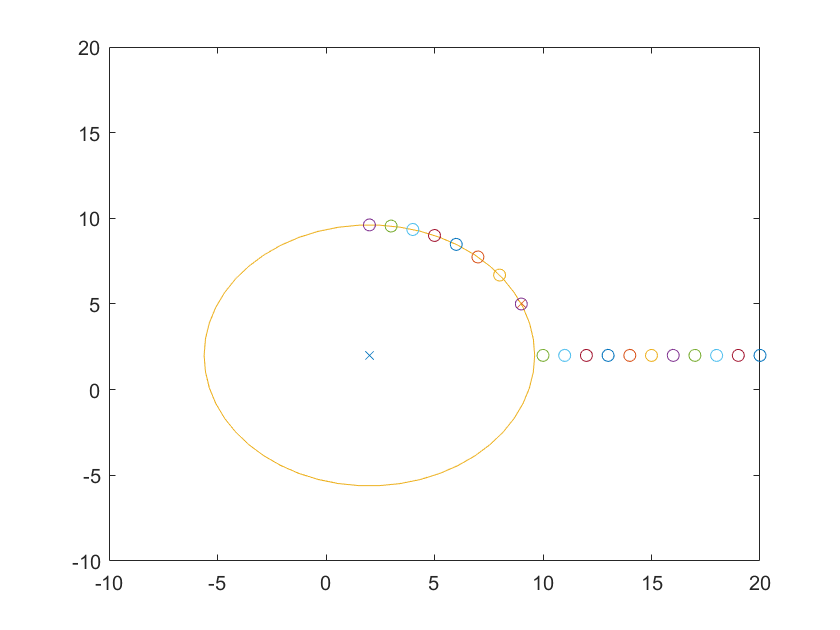

xlim([-10 20])
ylim([-10 20])